# Sessão 1 – 1.6 - Secção Biquadrática de Tow-Thomas

## 1.1 Objectivos

clear;

## 1.2 Equipamento para Ensaio Laboratorial

% Resistor values (Ohm)
R1 = 51e3;
R2 = 100e3;
R3 = 10e3;
R4 = 10e3;

R5 = 100e3;
R6 = 10e3;
R7 = 1e6;
R8 = 100e3;
R9 = 51e3;
R10 = 100e3;
R11 = 10e3;

% Potentiometer values (Ohm) 
P1 = 100e3; % (LOG)
P2 = 10e3; %(LIN)

% Capacitor values (F)
C1 = 4.7e-9;
C2 = 4.7e-9;

% Ampops = 741

## 1.3 Procedimento Experimental

Vin = 12; %(V)
Vin_ = -12; %(V)

## 1.6 Secção Biquadrática de Tow-Thomas

## 1.6.0 / 1.6.1

Circuito integrador de Miller (2R + 1C): $V_o(s)=-\frac{R_2||\frac{1}{Cs}}{R_1}V_1(s) = -\frac{R_2/R_1}{1+R_2Cs}V_1(s)$

Por combinação dos circuitos acima (teorema da sobreposição) vem

$V_2(s) = -\frac{1}{R_{11}C_2s}V_1(s)  \Rightarrow \frac{V_2(s)}{V_1(s)} = -\frac{1}{R_{11}C_2s}$,

$V_3(s) = -\frac{R_5}{R_2}V_2(s) \Rightarrow \frac{V_3(s)}{V_2(s)} = -\frac{R_5}{R_2}$,


$$V_1(s) = -\frac{R_6/P_2}{1+R_6C_1s}V_i(s) -\frac{R_6/R_4}{1+R_6C_1s}V_3(s) $$


Transfer functions are given by:

$T_1(s) = \frac{V_1(s)}{V_i(s)} = -\frac{\frac{1}{P_2C_1}s}{s^2+\frac{1}{R_6C_1}s+\frac{R_5}{R_2}\frac{1}{R_{4}R_{11}C_1C_2}}  =\frac{K\omega_0s}{s^2+(\omega_0/Q)s+G\omega_0^2}$  (BP),

$T_2(s) = \frac{V_2(s)}{V_i(s)} = \frac{\frac{1}{P_2R_{11}C_1C_2}}{s^2+\frac{1}{R_6C_1}s+\frac{R_5}{R_2}\frac{1}{R_{4}R_{11}C_1C_2}}  =\frac{K\omega_0^2}{s^2+(\omega_0/Q)s+G\omega_0^2}$ (LP),

$T_2(s) = \frac{V_3(s)}{V_i(s)} = \frac{\frac{R_5}{R_2}\frac{1}{P_2R_{11}C_1C_2}}{s^2+\frac{1}{R_6C_1}s+\frac{R_5}{R_2}\frac{1}{R_{4}R_{11}C_1C_2}}  =\frac{GK\omega_0^2}{s^2+(\omega_0/Q)s+G\omega_0^2}$ (LP).

Thus,

$\frac{1}{P_2C_1} = K\omega_0$,   $\frac{1}{R_6C_1} = \frac{\omega_0}{Q}$,   $\frac{R_5}{R_2}\frac{1}{R_{4}R_{11}C_1C_2} = G\omega_0^2$,   $\frac{1}{P_2R_{11}C_1C_2} = K \omega_0^2$,    $\frac{R_5}{R_2}\frac{1}{P_{2}R_{11}C_1C_2} = GK\omega_0^2$, which yields

$\omega_0 = \frac{1}{R_{11}C_2} = \frac{1}{\sqrt{R_4R_{11}C_1C_2}}$,   $G=\frac{R_5}{R_2}$,   $Q=\frac{R_6C_1}{R_{11}C_2}$,  $K=\frac{R_{11}C_2}{P_2C_1}=\frac{R_4}{P_{2}}$

omega_0 = 1/(R11*C2); % = 1/sqrt(R4*R11*C1*C2)
G = R5/R2;
Q = R6*C1/(R11*C2);
K = R4/P2; % = R11*C2/(P2*C1)
fprintf("omega_0 = %g rad/s | K = %g | Q = %g | G = %g\n",omega_0,K,Q,G);

omega_0 = 21276.6 rad/s | K = 1 | Q = 1 | G = 1


Transfer functions are then given by 

s = tf('s');
T1 = zpk(K*omega_0*s/(s^2+(omega_0/Q)*s+G*omega_0^2))


T1 =
 
            21277 s
  ----------------------------
  (s^2 + 2.128e04s + 4.527e08)
 
Continuous-time zero/pole/gain model.



T2 = zpk(K*omega_0^2/(s^2+(omega_0/Q)*s+G*omega_0^2))


T2 =
 
           4.5269e+08
  ----------------------------
  (s^2 + 2.128e04s + 4.527e08)
 
Continuous-time zero/pole/gain model.



T3 = zpk(G*K*omega_0^2/(s^2+(omega_0/Q)*s+G*omega_0^2))


T3 =
 
           4.5269e+08
  ----------------------------
  (s^2 + 2.128e04s + 4.527e08)
 
Continuous-time zero/pole/gain model.



## 1.6.2

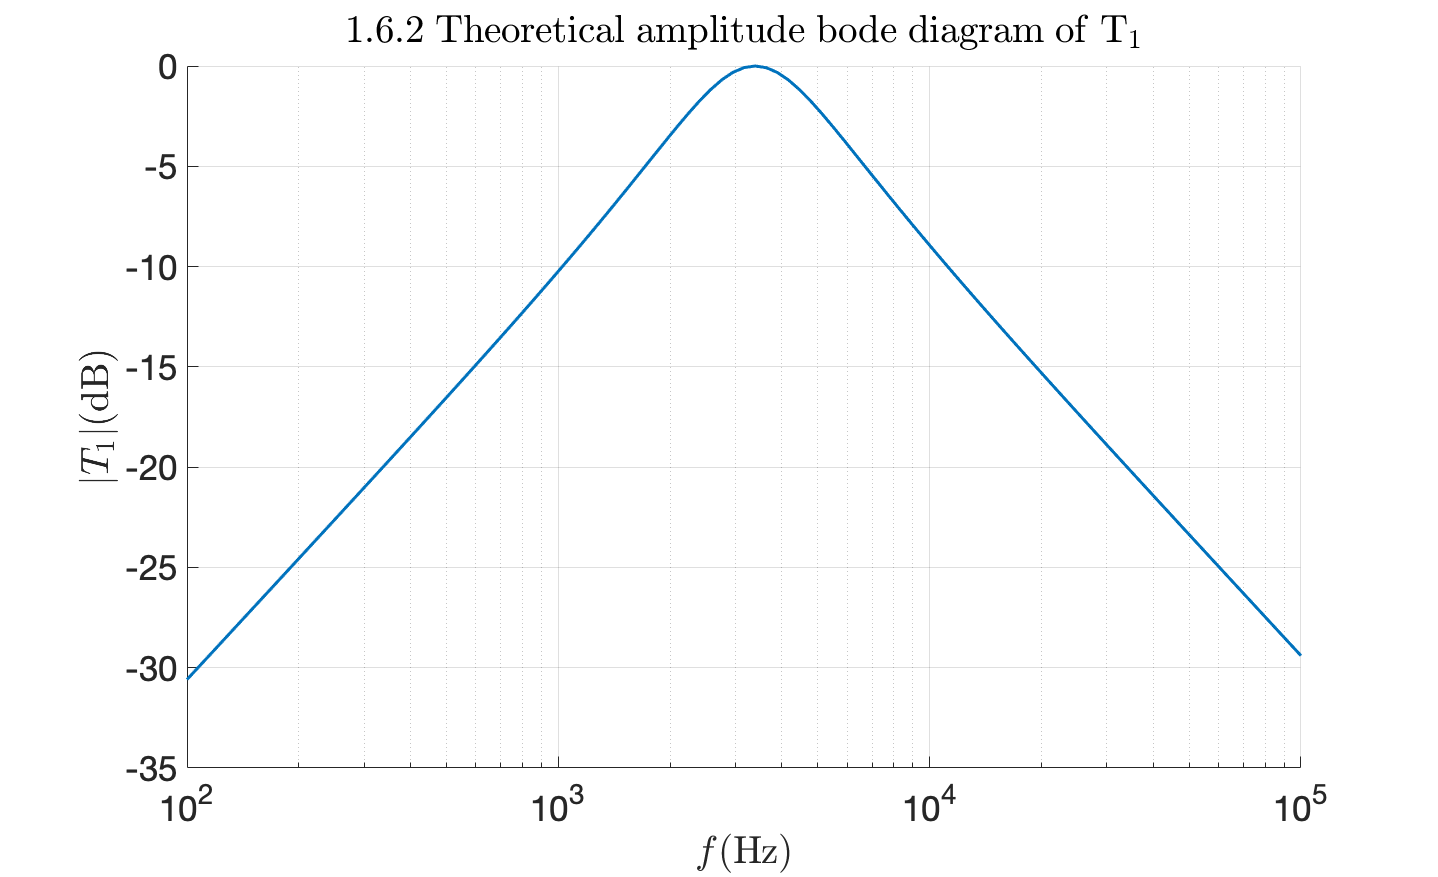

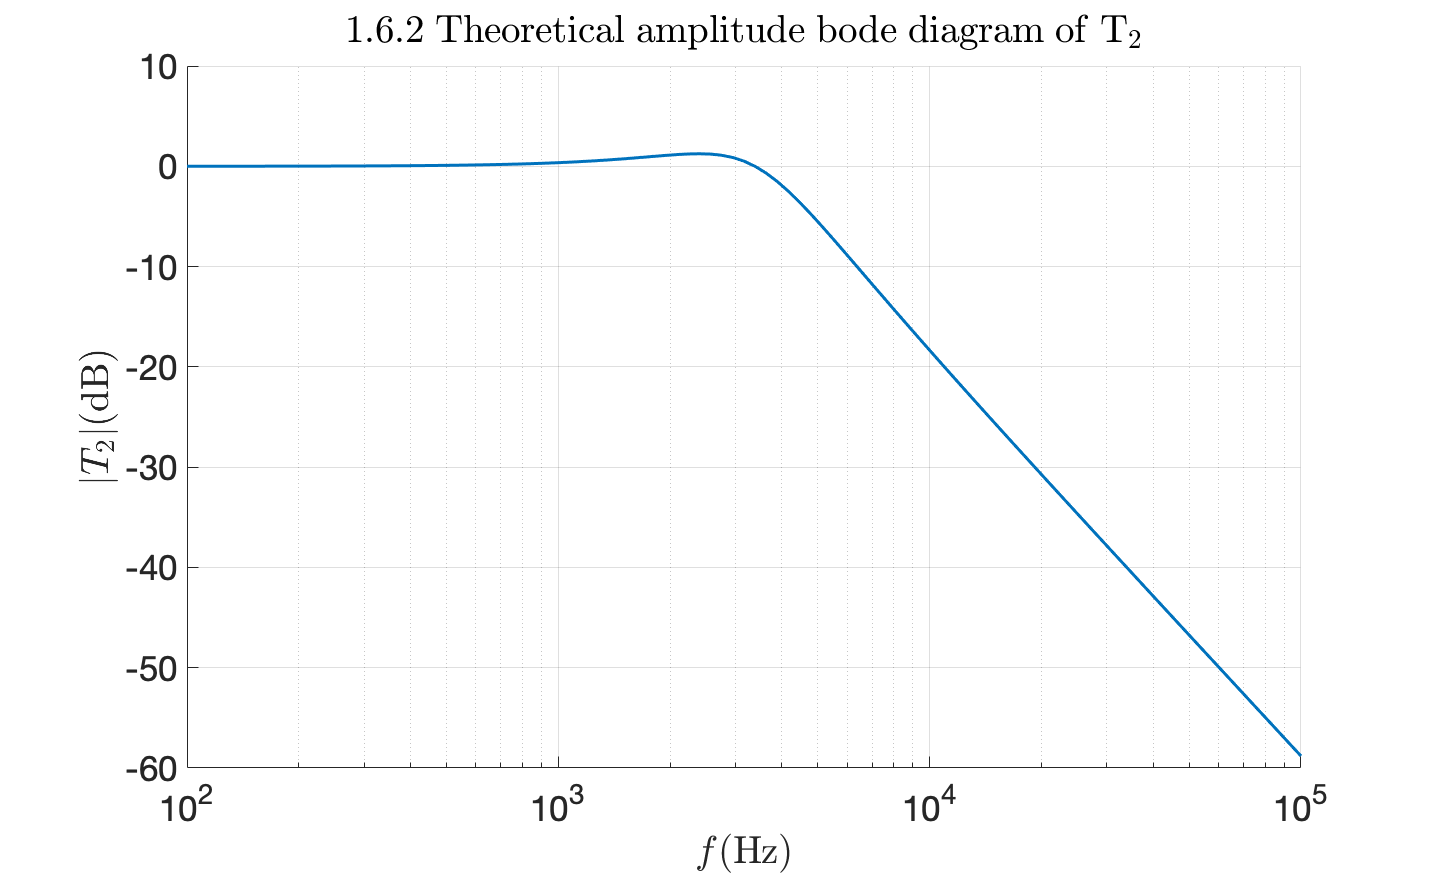

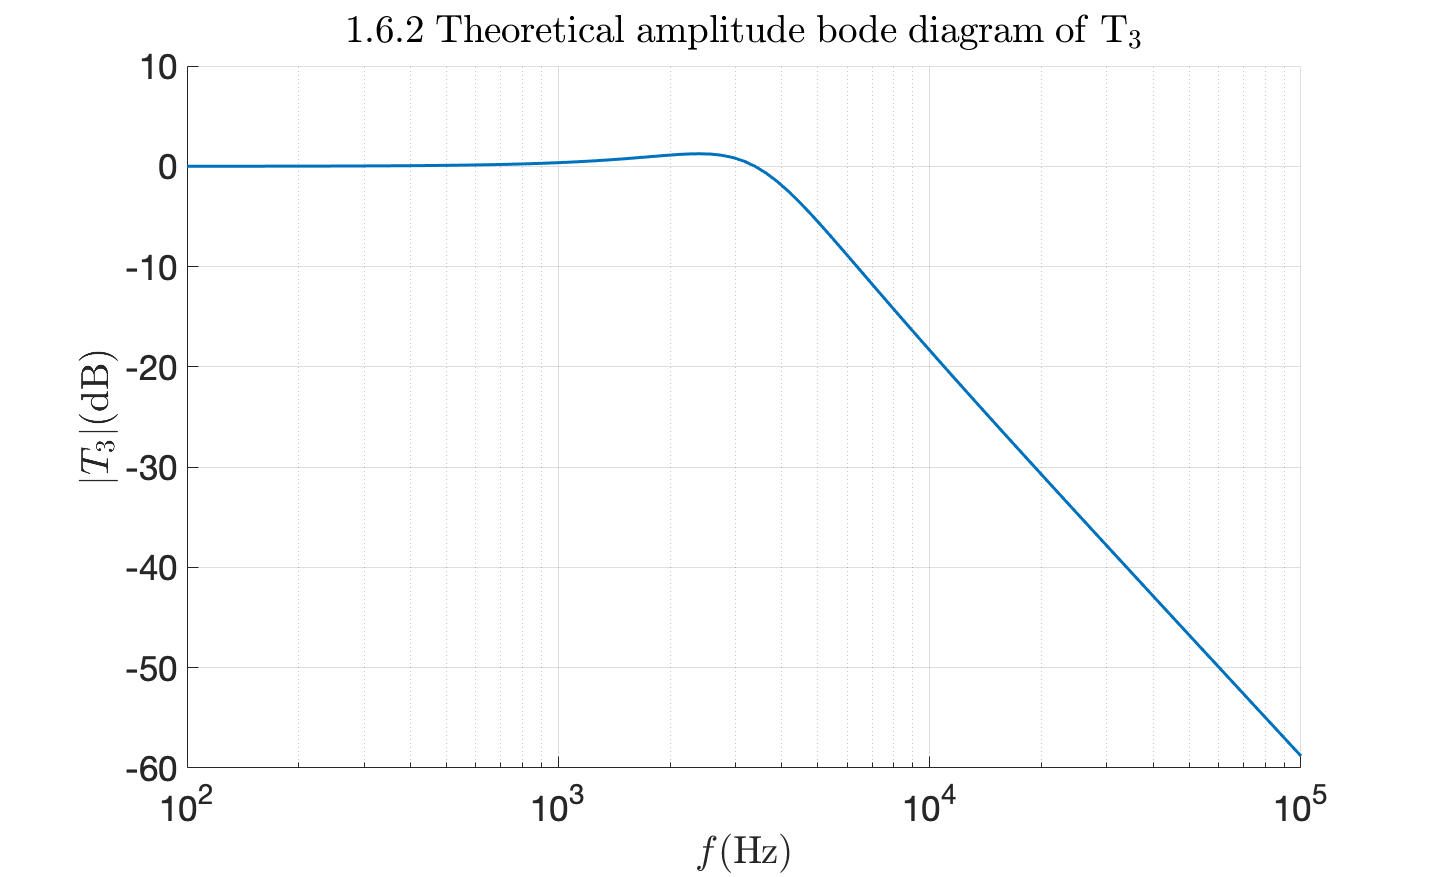

fLog = log10(100):(log10(100e3)-log10(100))/100:log10(100e3);
f = 10.^fLog;
gainBode = zeros(3,length(f));
for i = 1:length(f)
    gainBode(1,i) = 20*log10(abs(freqresp(T1,2*pi*f(i))));
    gainBode(2,i) = 20*log10(abs(freqresp(T2,2*pi*f(i))));
    gainBode(3,i) = 20*log10(abs(freqresp(T3,2*pi*f(i))));
end

for filter = 1:3
    figure('units','normalized','outerposition',[0 0 1 1]);
    hold on;
    set(gca,'FontSize',35);
    ax = gca;
    ax.XGrid = 'on';
    ax.YGrid = 'on';
    title(strcat('$1.6.2\; \mathrm{Theoretical\;amplitude\;bode\;diagram\;of}\;\mathrm{T}_',sprintf('%d$',filter)),'Interpreter','latex');
    plot(f,gainBode(filter,:),'LineWidth',3);
    set(gca,'xscale','log')
    ylabel(strcat(sprintf('$|T_%d|',filter),'\mathrm{(dB)}$'),'Interpreter','latex');
    xlabel('$f \mathrm{(Hz)}$','Interpreter','latex');
    saveas(gcf,sprintf('./Session1DATA/1_6_2_bodeTheoretical%d.fig',filter));
    saveas(gcf,sprintf('./Session1DATA/1_6_2_bodeTheoretical%d.png',filter));
    hold off; 
end

## 1.6.3

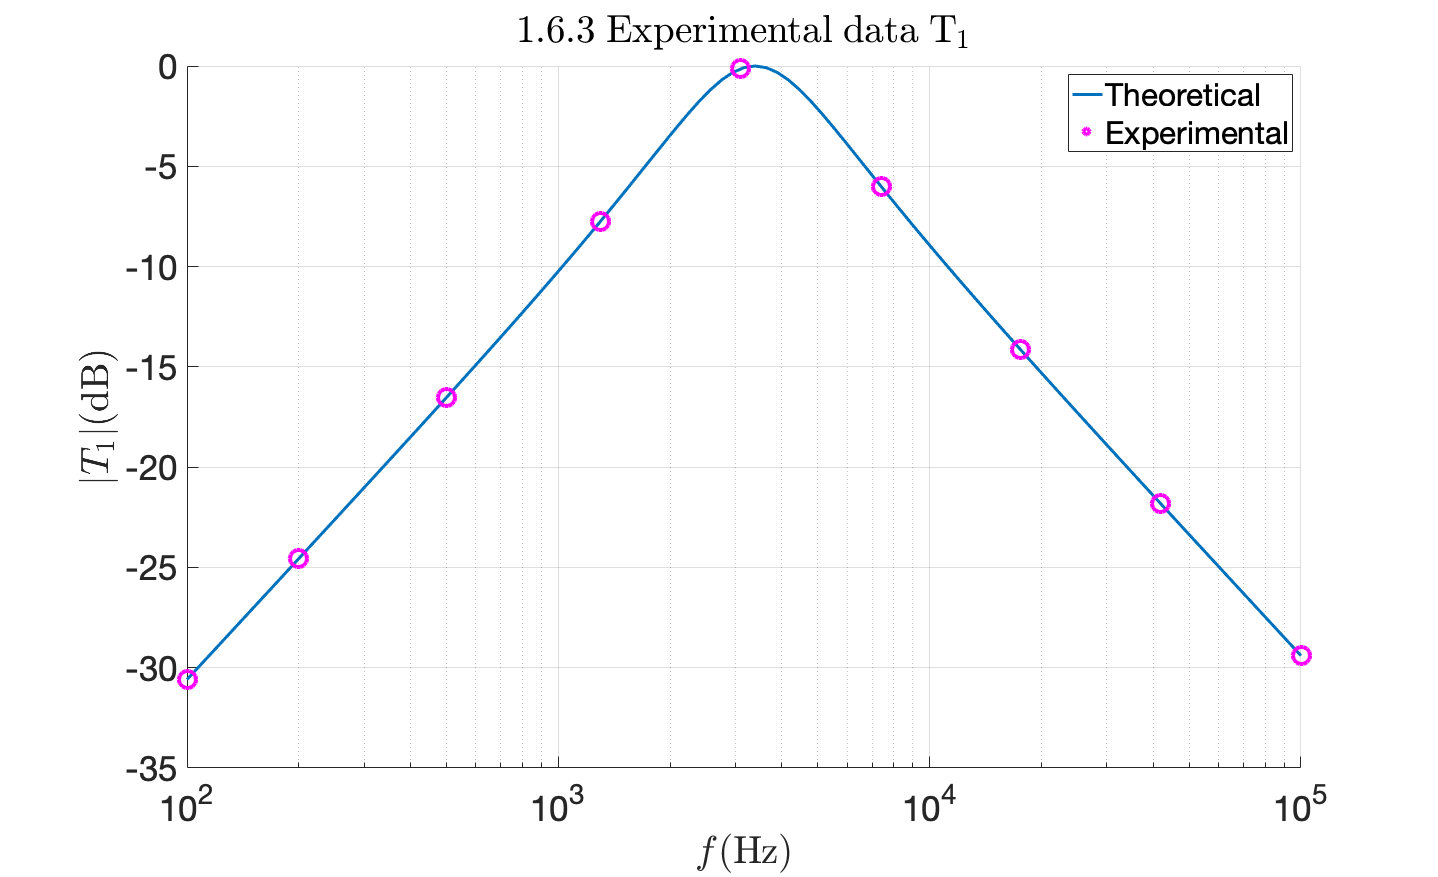

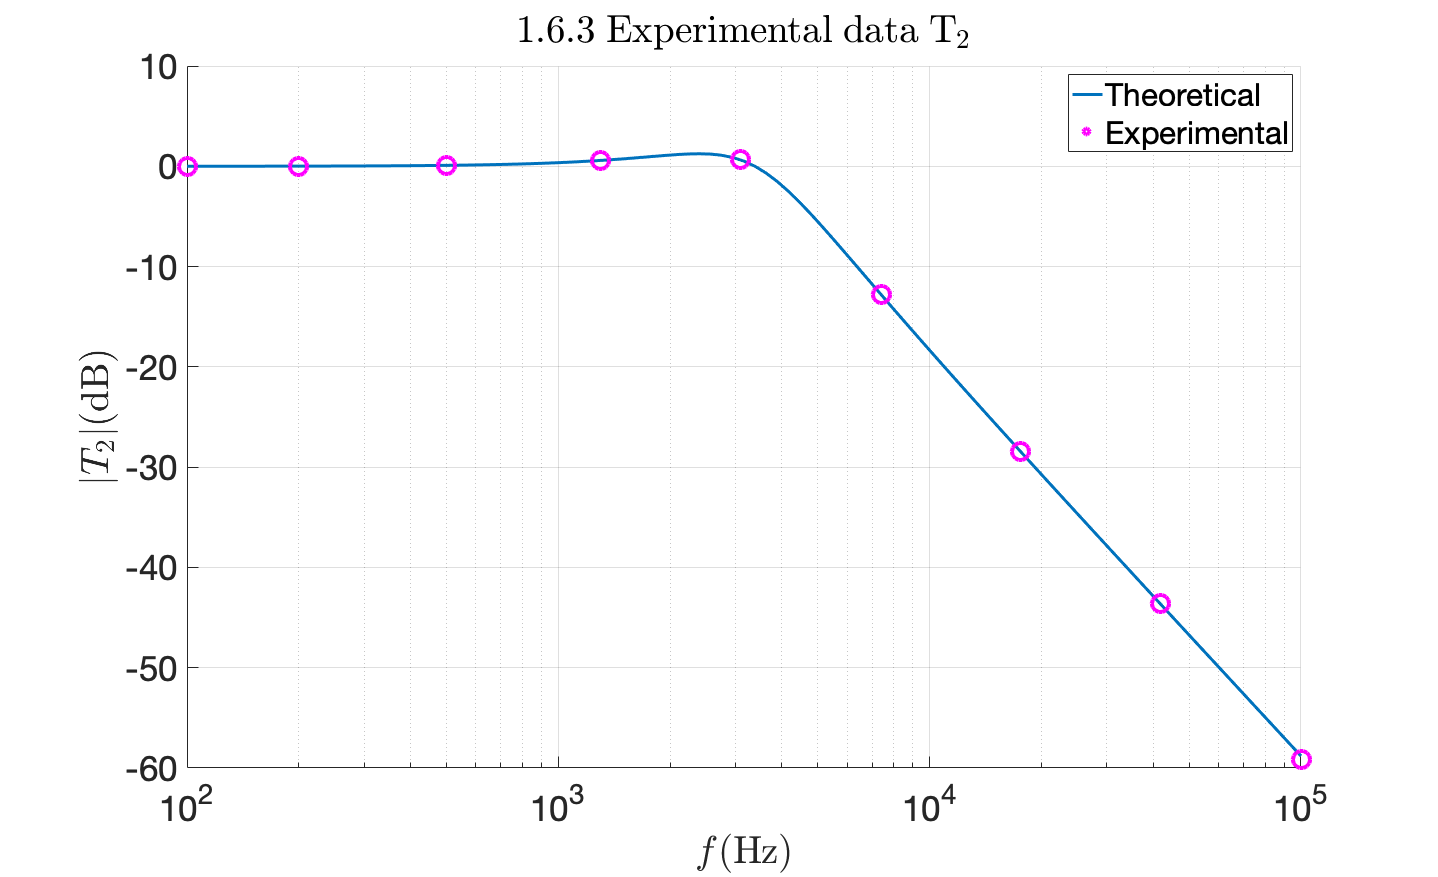

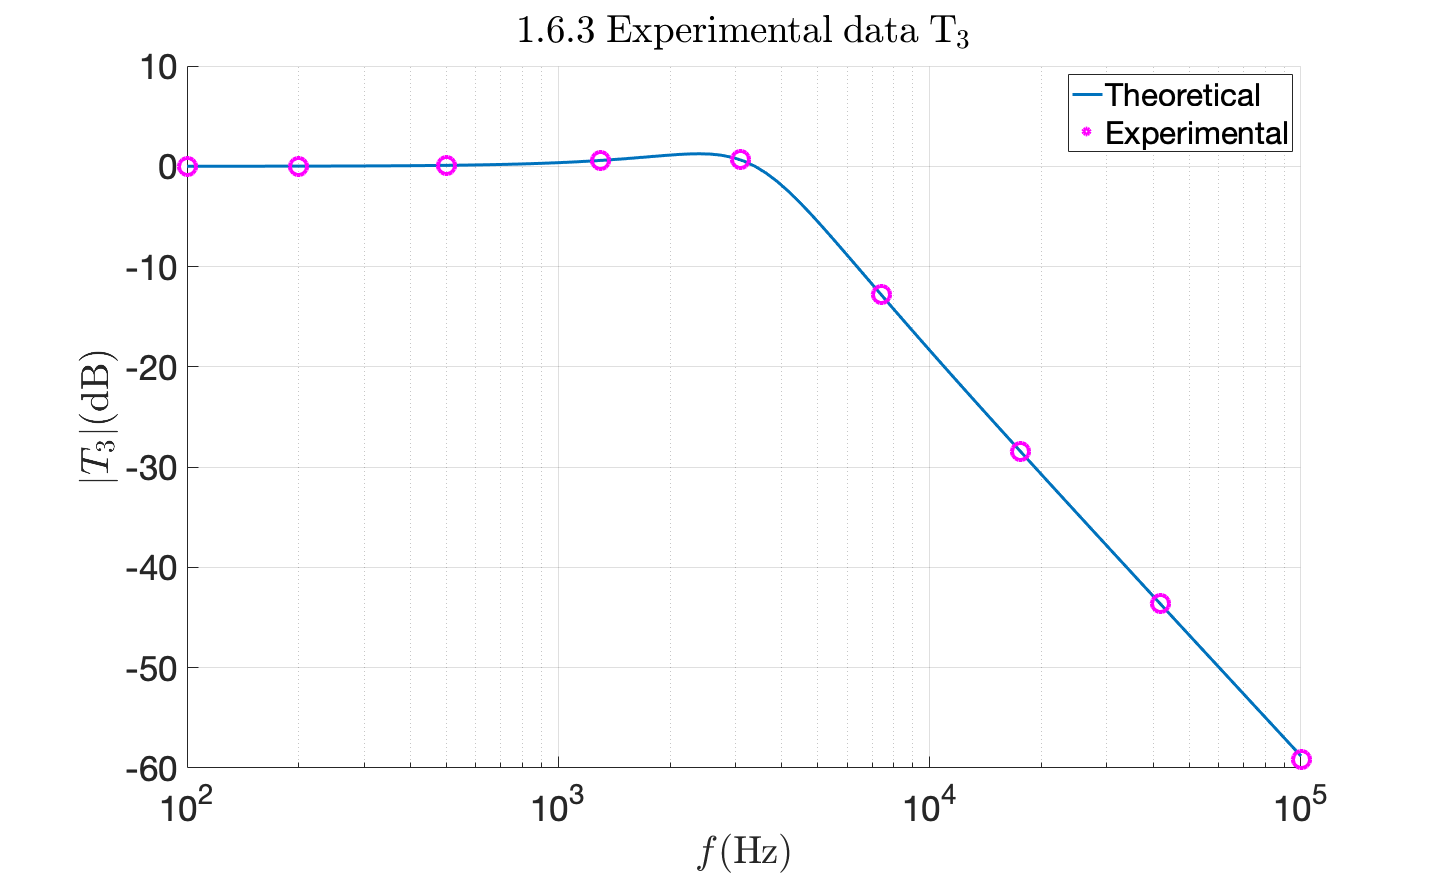

% Amostragem uniforme
% fLogExp = 1.6:(log10(100e3)-1.6)/9:log10(100e3);
% fExp = round((10.^fLogExp)/100)*100;
% gainBodeExp = zeros(3,length(fExp));
% VAmp = 1; %(V)
% for freqN = 1:length(fExp)
%     gainBodeExp(1,freqN) = abs(freqresp(T1,2*pi*fExp(freqN)));
%     gainBodeExp(2,freqN) = abs(freqresp(T2,2*pi*fExp(freqN)));
%     gainBodeExp(3,freqN) = abs(freqresp(T3,2*pi*fExp(freqN)));
% end
% VoutExp = VAmp*gainBodeExp;
% gainBodeExp = 20*log10(abs(gainBodeExp));

% Experimental data
VAmp = 1; %(V)
dataExp = importdata('./Session1Exp/1_6_3_exp.txt');
fExp = dataExp(:,1)';
VExp = dataExp(:,2:4)';
gainBodeExp = 20*log10(abs(VExp/VAmp));

for filter = 1:3
    figure('units','normalized','outerposition',[0 0 1 1]);
    hold on;
    set(gca,'FontSize',35);
    ax = gca;
    ax.XGrid = 'on';
    ax.YGrid = 'on';
    title(strcat('$1.6.3\; \mathrm{Experimental\;data}\;\mathrm{T}_',sprintf('%d$',filter)),'Interpreter','latex');
    plot(f,gainBode(filter,:),'LineWidth',3);
    scatter(fExp,gainBodeExp(filter,:),300,'o','magenta','LineWidth',4);
    legend('Theoretical','Experimental');
    set(gca,'xscale','log')
    ylabel(strcat(sprintf('$|T_%d|',filter),'\mathrm{(dB)}$'),'Interpreter','latex');
    xlabel('$f \mathrm{(Hz)}$','Interpreter','latex');
    saveas(gcf,sprintf('./Session1DATA/1_6_3_bodeExperimental%d.fig',filter));
    saveas(gcf,sprintf('./Session1DATA/1_6_3_bodeExperimental%d.png',filter));
    hold off; 
end

## 1.6.4

É fácil de verificar que tanto $Q$ como $\omega_0$ não dependem do valor de $P_2$, unicamente o ganho do filtro sofre modificações:

$K=\frac{R_{11}C_2}{P_2C_1}=\frac{R_4}{P_{2}}$.

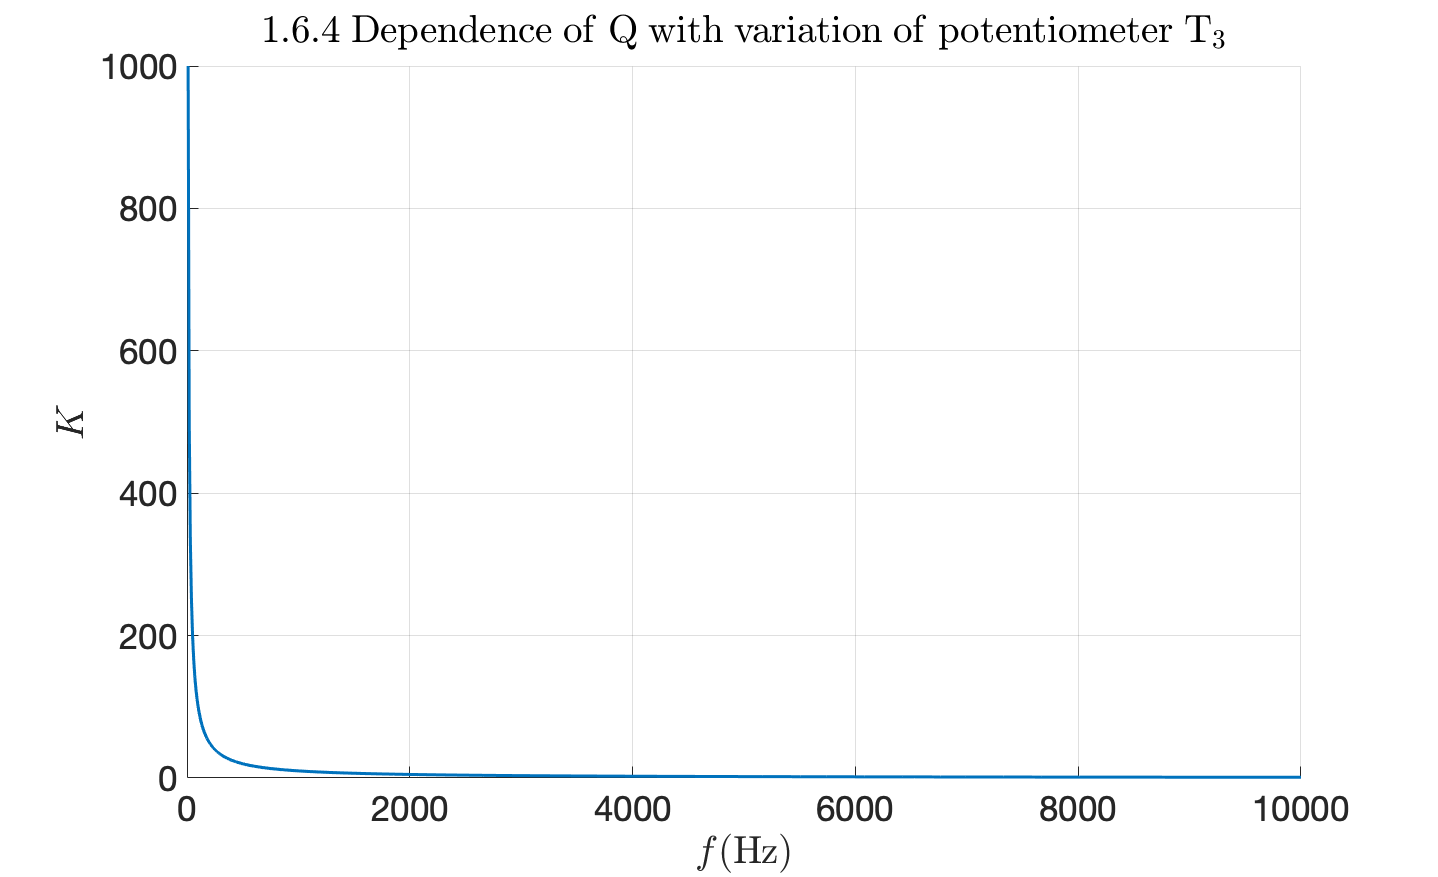

P2_ = 0:10e3/1000:10e3;
K_ = R4./P2_;
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
set(gca,'FontSize',35);
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'on';
title(strcat('$1.6.4\; \mathrm{Dependence\;of\;Q\;with\;variation\;of\;potentiometer}\;\mathrm{T}_',sprintf('%d$',filter)),'Interpreter','latex');
lg = [];
plot(P2_,K_,'LineWidth',3);
ylabel('$K$','Interpreter','latex');
xlabel('$f \mathrm{(Hz)}$','Interpreter','latex');
saveas(gcf,sprintf('./Session1DATA/1_6_4_GainPotentiometer%d.fig',filter));
saveas(gcf,sprintf('./Session1DATA/1_6_4_GainPotentiometer%d.png',filter));
hold off; 

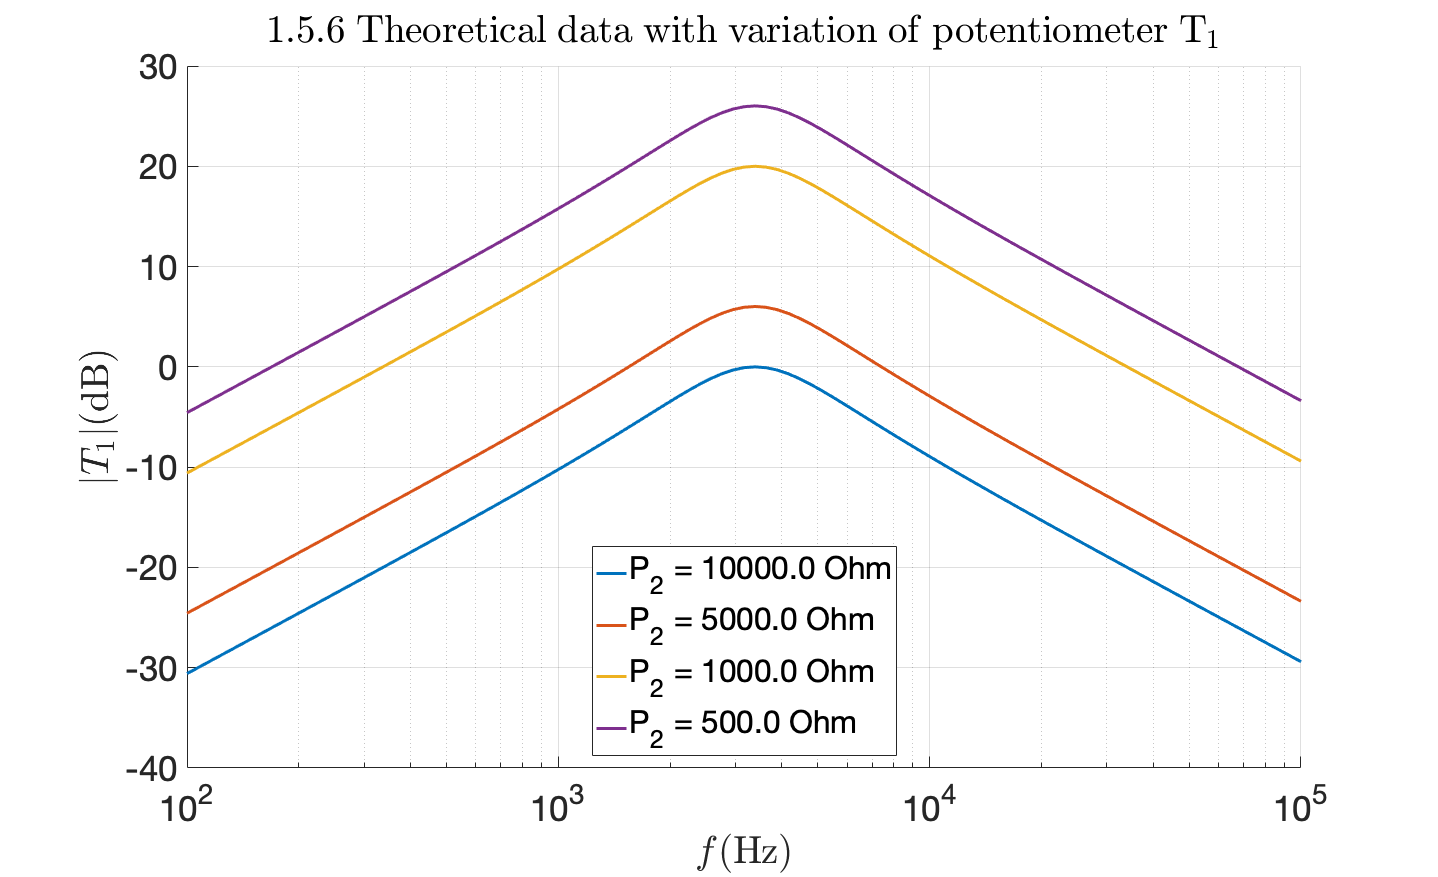

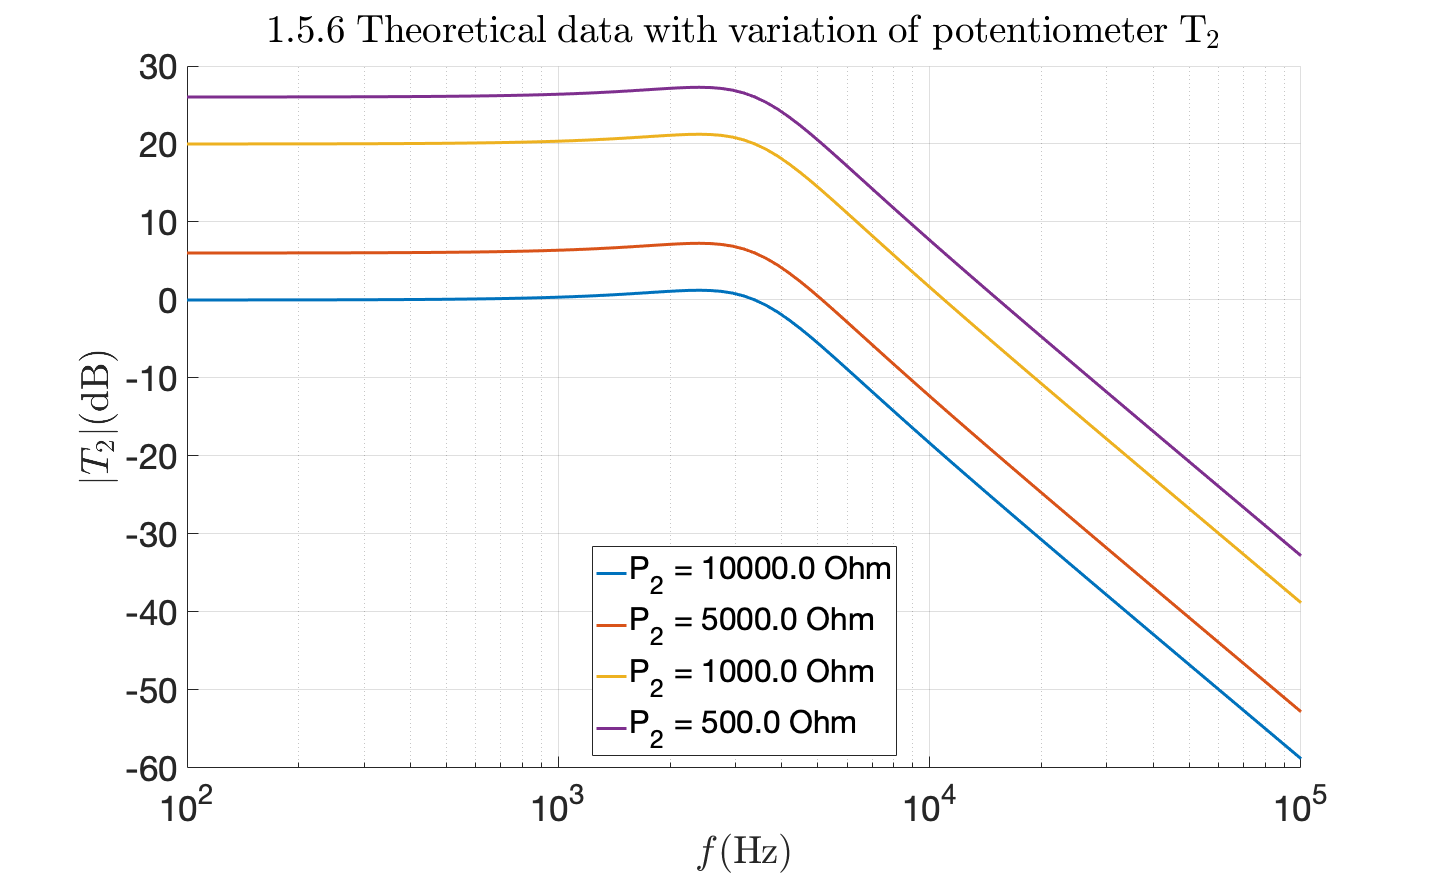

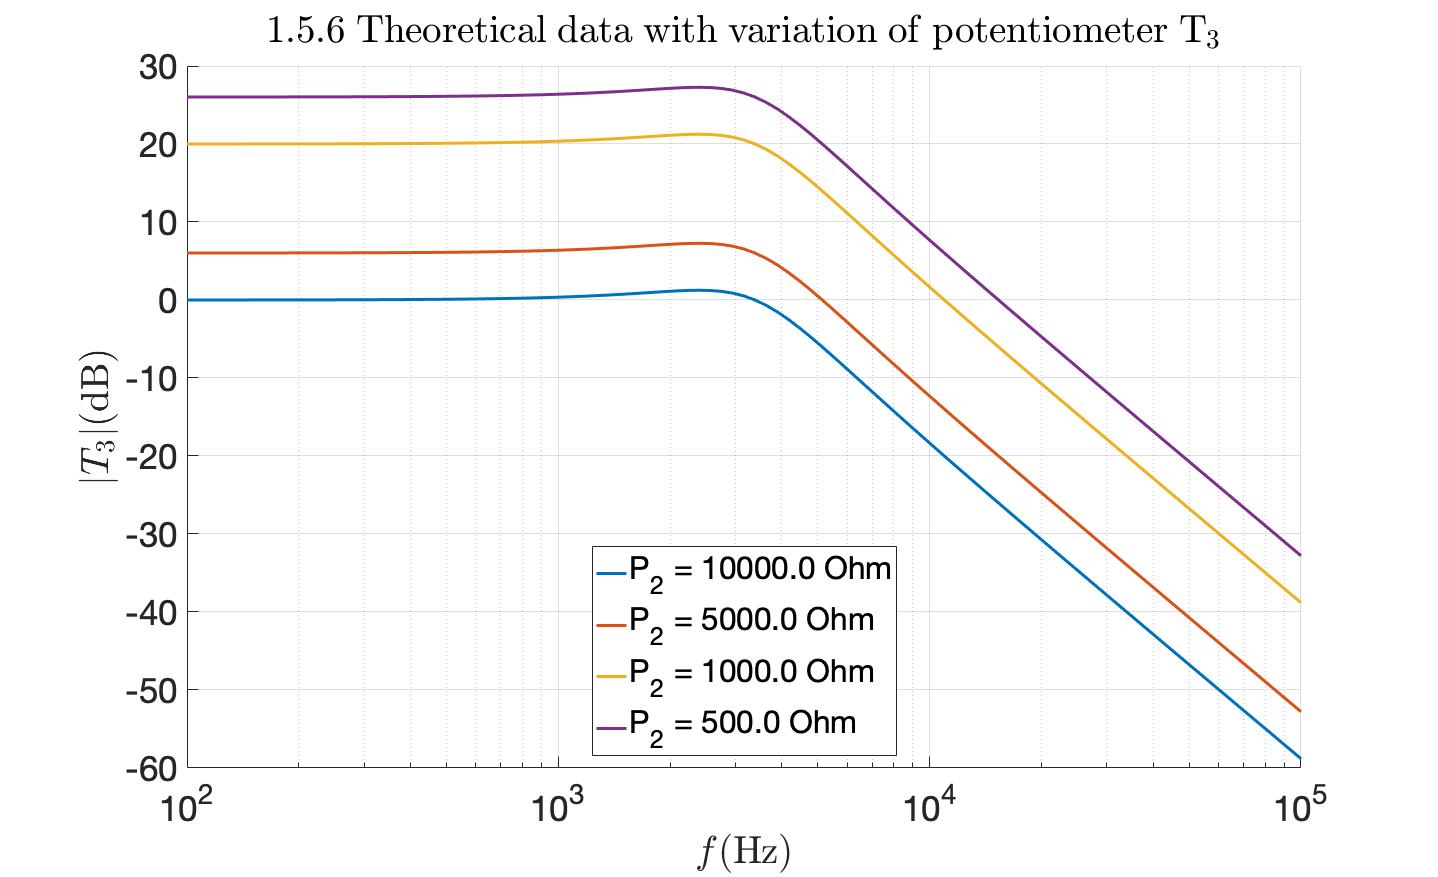

P2_ = [10e3 5e3 1e3 0.5e3]; % (Ohm) 
K_ = R4./P2_;
T_ = cell(3,length(P2_));
for i = 1:length(P2_)
    T_{1,i} = zpk(K_(i)*omega_0*s/(s^2+(omega_0/Q)*s+G*omega_0^2));
    T_{2,i} = zpk(K_(i)*omega_0^2/(s^2+(omega_0/Q)*s+G*omega_0^2));
    T_{3,i} = zpk(G*K_(i)*omega_0^2/(s^2+(omega_0/Q)*s+G*omega_0^2));
end

gainBode_ = zeros(3,length(f),length(P2_));
for i = 1:length(f)
    for filter = 1:3
        for j = 1:length(P2_)
            gainBode_(filter,i,j) = 20*log10(abs(freqresp(T_{filter,j},2*pi*f(i))));
        end
    end
end

for filter = 1:3
    figure('units','normalized','outerposition',[0 0 1 1]);
    hold on;
    set(gca,'FontSize',35);
    ax = gca;
    ax.XGrid = 'on';
    ax.YGrid = 'on';
    title(strcat('$1.5.6\; \mathrm{Theoretical\;data\;with\;variation\;of\;potentiometer}\;\mathrm{T}_',sprintf('%d$',filter)),'Interpreter','latex');
    lg = [];
    for i = 1:length(P2_)
        plot(f,gainBode_(filter,:,i),'LineWidth',3);
        lg = [lg sprintf("P_2 = %.01f Ohm",P2_(i))];
    end
    legend(lg,'Location','best');
    set(gca,'xscale','log');
    ylabel(strcat(sprintf('$|T_%d|',filter),'\mathrm{(dB)}$'),'Interpreter','latex');
    xlabel('$f \mathrm{(Hz)}$','Interpreter','latex');
    saveas(gcf,sprintf('./Session1DATA/1_6_4_bodeTheoreticalPotentiometer%d.fig',filter));
    saveas(gcf,sprintf('./Session1DATA/1_6_4_bodeTheoreticalPotentiometer%d.png',filter));
    hold off; 
end

## 1.6.5

k: com ganho estático no passa baixo

ordem: com -20 dB/dec nos ramos em que desce assitoticamente

Achar Q e w0 faz se regressão?

k pelo passa baixo

Ou faz-se regressao a tudo e pronto!! (mais vale)

## Perguntas